# Extended kalman Filter

## ROBOT SETUP

clear ;
warning('off');
initPose = [4; % x
            20; % y
            -0.7];% Tetha


**Noise in velocities with 0 mean and variance:**

varianceV= 0.1; %.3 
varianceW= 0.13; % .1
 
varianceR = 0.5;
varianceT = 0.05;

**Covariance Matrixes **

   

Q = [0.00001 0  0; 
     0 0.000001  0; 
     0 0  0.00001];
     
     
 R = [0.03 0 0;
      0 0.002 0;
      0 0 1e-11];
 
 alpha= [ 0.02
          0.0001
          0.001
          0.00001 ];
 
 % alpha1  Specifies the expected noise in odometry's rotation estimate from the rotational component of the robot's motion.
 % alpha2  Specifies the expected noise in odometry's rotation estimate from translational component of the robot's motion.
 % alpha3  Specifies the expected noise in odometry's translation estimate from the translational component of the robot's
 % alpha4  Specifies the expected noise in odometry's translation estimate from the rotational component of the robot's motion.
 

**Waypoints and landmarks coordinates**

 waypoints = [   10 10;
                 20 15;
                 40 10;
                 63 5;
                 82 40;
                 65 55;
                 45 60;
                 23 75;
                 5 80];

landmak_coordinates= [ 10 10;
                       40 4;
                       30 20;
                       50 3;
                       58 13;
                       65  13;
                       65  30;
                       60 40;
                       86 40;
                       80 22; 
                       59 60;
                       35 50;
                       35 80;
                       50 65;
                       45 63;
                       2 80;
                       23 83];

### Robot configuration

    WR = 0.1;   % Wheels radio [m]
    BR = 0.5;   % Base radio [m]
    dd = DifferentialDrive(WR,BR);

#### Object detector setup

    detector = ObjectDetector;
    detector.fieldOfView = pi; % Field of View
    detector.maxRange = 20; % Max range distance [m]        
    detector.maxDetections = 5; % Max number of detections   

#### Lidar setup

    lidar = LidarSensor;
    lidar.sensorOffset = [0,0]; %Placed at robot center
    lidar.scanAngles = linspace(-pi/2,pi/2,51); % Angles of each laser
    lidar.maxRange = 15; %Max distance range

#### Field setup

Read map from an image (prefered binary image) and convert  it to a binaryOcucupancyMap

    addpath('.\maps')
    image = imread('office.png');
    grayimage = rgb2gray(imresize(image, 1.0));
    bwimage = grayimage < 0.1;
    map = binaryOccupancyMap(bwimage);

Landmarks setup

    [n, ~] = size(landmak_coordinates);
    colors = zeros(n,3);
    objects = zeros(n,3);
    markers='';
    for i=1:n
        %Set x,y and id for each landmark
        objects(i,1) = landmak_coordinates(i,1);
        objects(i,2) = landmak_coordinates(i,2);
        objects(i,3) = i;
        %Set color for each landmark
        colors(i,1) = .3;
        colors(i,2) = .8;
        colors(i,3) = .5;
        %Set marker for each landmark
        markers = strcat(markers,'s');
    end

Setup Visualizer

    viz = Visualizer2D;
    viz.hasWaypoints = true;
    viz.mapName = 'map';
    
    %Attach sensors
    attachLidarSensor(viz,lidar);
    attachObjectDetector(viz,detector);
    
    % Set Color and marker for landmarks
    viz.objectColors = colors;
    viz.objectMarkers = markers;
    

Algorithms setup

    % Pure Pursuit Controller for robot movements
    controller = controllerPurePursuit;
    controller.Waypoints = waypoints;
    controller.LookaheadDistance = 0.5;
    controller.DesiredLinearVelocity = 1.0;
    controller.MaxAngularVelocity = 1.5;

    % Vector Field Histogram (VFH) for obstacle avoidance
    vfh = controllerVFH;
    vfh.DistanceLimits = [BR 6];
    vfh.NumAngularSectors = 36;
    vfh.HistogramThresholds = [5 10];
    vfh.RobotRadius = BR;
    vfh.SafetyDistance = 3;
    vfh.MinTurningRadius = 0.25;

 SIMULATION SETUP


    % Sample time and time array
    sampleTime = 0.1;              % Sample time [s]
    tVec = 0:sampleTime:215;        % Time array
    r = rateControl(1/sampleTime);

    %Ideal Pose  (ODOMETRY)
    pose = zeros(3,numel(tVec));   % Pose matrix
    pose(:,1) = initPose;   % set first pose as the initial position

    %Pose with added noise (REAL MOVEMENTS) 
    poseWithNoise = zeros(3,numel(tVec)); 
    poseWithNoise(:,1) = initPose;  %Same initial pose
    
    
    %Kalman Pose (KALMAN LOCALIZATION)
    poseKalman = zeros(3,numel(tVec));   % Pose matrix
    poseKalman(:,1) = initPose;   % set first pose as the initial position
    
    sv = initPose; %State vector initialization
    
    sigma = [0 0 0; 0 0 0; 0 0 0];
    meanValueV = 0;
    meanValueW = 0;

      %%% SIMULATION
     eFig1 = figure;
     eAxes1 = gca;
     ePlot1 = plot(NaN,NaN,'r');
     title('Error in axis Y');
     grid on
     
     eFig2 = figure;
     eAxes2 = gca;
     ePlot2 = plot(NaN,NaN,'g');
     title('Error in axis X');
     grid on
     
     eFig3 = figure;
     eAxes3 = gca;
     ePlot3 = plot(NaN,NaN,'b');
     title('Numbers of LandMarks');
     grid on
     
     
    numberDetections = zeros(1,numel(tVec)); 
    
    
    

Executing simulation

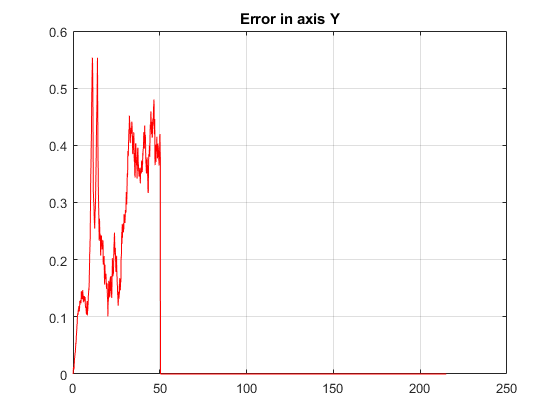

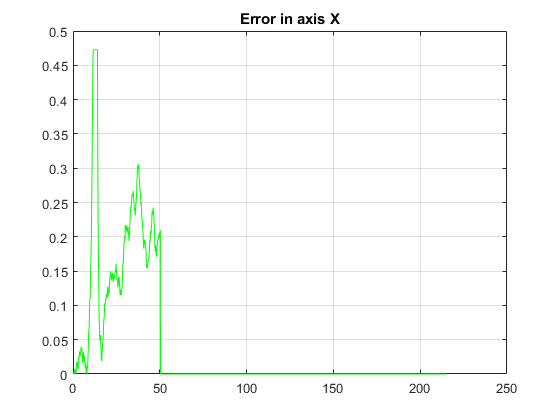

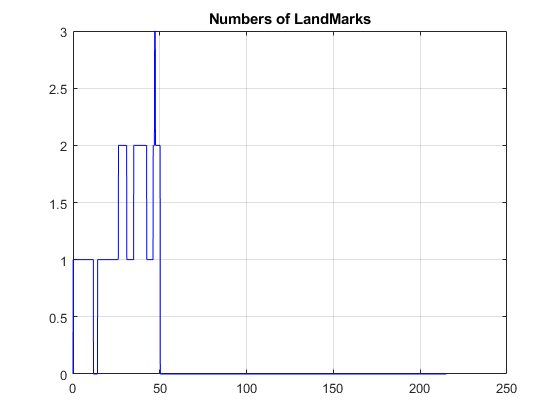

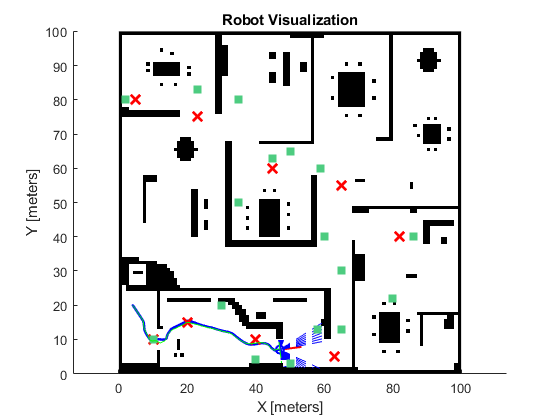


for idx = 2:numel(tVec) 
    
    %Update pose
    curPoseFake = pose(:,idx-1);
    curPoseReal = poseWithNoise(:,idx-1);
    curPoseKalman = poseKalman(:,idx-1);  
    
    % Get the sensor readings from the real pose
    ranges = lidar(curPoseReal);
        
    % Run the path following and obstacle avoidance algorithms
    wp = curPoseKalman;
    %wp = curPoseFake;
    
    [vRef,wRef,lookAheadPt] = controller(wp);
    targetDir = atan2(lookAheadPt(2)-wp(2),lookAheadPt(1)-wp(1)) - wp(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    velBFake = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    
    %%Add Noise 
    vRef = vRef + abs(normrnd(0,varianceV)); % abs((sqrt(varianceV)*randn(size(vRef)) + meanValueV));
    wRef = wRef + normrnd(0,varianceW); %(sqrt(varianceW)*randn(size(vRef)) + meanValueW/2);
    
    % Control the robot
    velBReal = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    
    velFake = bodyToWorld(velBFake,curPoseFake);  % Convert from body to world
    velReal = bodyToWorld(velBReal,curPoseReal);  % Convert from body to world
    
    
    % Perform forward discrete integration step
    pose(:,idx) = curPoseFake + velFake*sampleTime; 
    poseWithNoise(:,idx) = curPoseReal + velReal*sampleTime; 
    
      
    % Update object detector and visualization
    detections = detector(poseWithNoise(:,idx),objects);
    viz(poseWithNoise(:,idx),waypoints,ranges,objects);
    
    
    
    
    for i = 1:size(detections,1)
        detections(i,1) = detections(i,1) + normrnd(0,varianceR);
        detections(i,2) = detections(i,2) + normrnd(0,varianceT);
    end
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%
    %                        %
    % Extended Kalman Filter %
    %                        %
    %%%%%%%%%%%%%%%%%%%%%%%%%%
    
    % Prediction step
    
    [sv, u] = sampleOdometry(pose(:,idx-1),pose(:,idx),sv,alpha);
    
    
    %Jacobian of function g(sv,u)
    G = [ 1 0 -u(1)*sin(u(2));
          0 1  u(1)*cos(u(2));
          0 0         1       ];
  
    sigma =  G*sigma*G.' + Q;
    
    %End prediction
    
    
    %Actualization step for each landmark detected at the moment
    for i = 1:size(detections,1)
        
        %Real measurement
         z = [ detections(i,1);
               detections(i,2) ;
               0                 ];
          
        %Get landmark id
        for j = 1:size(objects,1)
            if objects(j,3) == detections(i,3)
                id_landmark = j;
            end
        end
        
        
        dist = power(objects(id_landmark,1) - sv(1), 2) + power(objects(id_landmark,2) - sv(2), 2); % Radicando de la de la distancia entre un landmark y el robot 
        
        %Computing sensor readings spected
        z_hat = [ sqrt(dist);
                  normalizeAngle(  atan2(objects(id_landmark,2) - sv(2), objects(id_landmark,1) - sv(1) ) - sv(3) ) ;
                  0];
              
        % Jacobian of function h(sv)
        H = [ -( objects(id_landmark,1) - sv(1) ) / sqrt(dist),  -( objects(id_landmark,2) - sv(2) ) / sqrt(dist), 0;
            ( objects(id_landmark,2) - sv(2)) / dist, -( objects(id_landmark,1) - sv(1) ) / dist,-1;
			 	  0,0,0];
        
       L = (H*sigma*(H.')) + R;
       
       %Computing Kalman gain
       K =  (sigma* (H.')) /(L);
       V = z-z_hat;
       
       %Update state vector (sv) and covarianz matrix (sigma)
       sv = sv +  (K*V);
       sigma = (eye(3) - (K*H)  ) * sigma;
       
       sv(3) = normalizeAngle(sv(3));
        
    end
    
    %Updating error graphs and path vectors
    poseKalman(:,idx) = sv;
    hold on;
    plot( poseKalman(1,1:idx), poseKalman(2,1:idx),'g');
    numberDetections(idx) = size(detections,1);
    set(ePlot1,'XData',tVec,'YData',abs(poseKalman(1,:) - poseWithNoise(1,:)) );
    set(ePlot2,'XData',tVec,'YData',abs(poseKalman(3,:) - pose(3,:)) );
    set(ePlot3,'XData',tVec,'YData',numberDetections );

    %Wait fot visualization rate
    waitfor(r);
  
end


% Update object detector and visualization
viz(poseWithNoise(:,idx),waypoints,ranges,objects);
hold on

%% show path with noise and ideal path 
plot(pose(1,:),pose(2,:),'m');
plot(poseWithNoise(1,:),poseWithNoise(2,:),'k');
plot( poseKalman(1,:), poseKalman(2,:),'g');

